Dataset:

close all
clc
path = '/Users/veron/OneDrive - Politecnico Di Milano/fintech/Lab/Zenti_BusinessCase1/BankClients.mat';
% Example:
% path = '/Users/raffaelezenti/Dropbox (virtualb)/RaffaeleZenti/MyMatlab/Laboratorio_Politecnico_Milano/BankClients.mat';
load(path)

% Numerical
N = vartype('numeric');
Data = BankClients(:,2:end); % Exclude 1st col = ID
NumFeatures = Data(:,N); % subtable of numerical features
XNum = NumFeatures.Variables; 
XNum = rescale(XNum); % normalize in [0, 1]

% Categorical
C = vartype('categorical');
CatFeatures = Data(:,C); % subtable of categorical features

% Encoding (ie create dummy variables)
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end-1)]; % To use the dummy variables in a model, we must delete a column
end


X = [XCat XNum];


%subsample
nSubSample = 1000;
rng('default') % for reproducibility
randRows = randperm(size(X, 1), nSubSample);
X = X(randRows', :);

choose of the metric

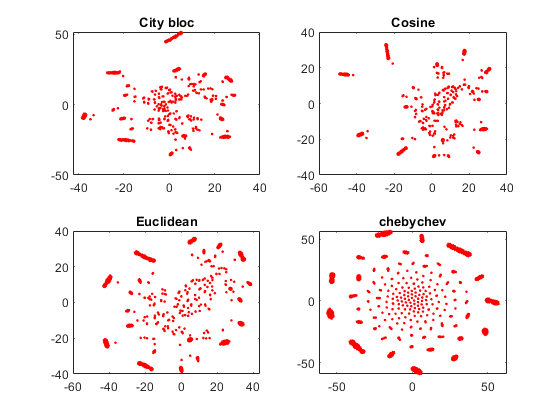

rng('default') % for reproducibility
Y = tsne(X,'Algorithm','exact','Distance','citybloc');
subplot(2,2,1)
gscatter(Y(:,1),Y(:,2))
title('City bloc')

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance','cosine');
subplot(2,2,2)
gscatter(Y(:,1),Y(:,2))
title('Cosine')

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance','euclidean');
subplot(2,2,3)
gscatter(Y(:,1),Y(:,2))
title('Euclidean')

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance','chebychev');
subplot(2,2,4)
gscatter(Y(:,1),Y(:,2))
title('chebychev')

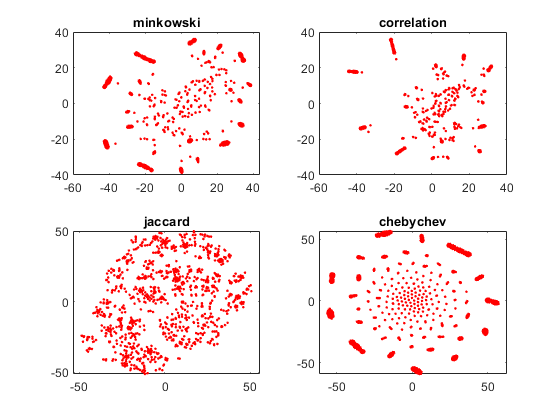

hold on
rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance','minkowski');
subplot(2,2,1)
gscatter(Y(:,1),Y(:,2))
title('minkowski')

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance','correlation');
subplot(2,2,2)
gscatter(Y(:,1),Y(:,2))
title('correlation')

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance','jaccard');
subplot(2,2,3)
gscatter(Y(:,1),Y(:,2))
title('jaccard')

hold off


DBSCAN:

The key intuition behind DBSCAN is that a point belongs to a cluster if it is close to many points from that cluster.

DBSCAN identifies arbitrarily shaped clusters and noise (outliers) in data. We can perform clustering on an input data matrix or on pairwise distances between observations, which is our case, and the function `dbscan`r eturns the cluster indices and a vector indicating the observations that are core points (points inside clusters). Unlike other clustering methods, the DBSCAN algorithm** does not require prior knowledge of the number of clusters** (and **clusters are not necessarily spheroidal**). 

When it comes to arbitrary shaped clusters or detecting outliers, density-based techniques are more efficient, and can be used with categorical data, if we use the proper distance metrix - like we are supposed to do.

For a point to be assigned to a cluster, it must satisfy the condition that its epsilon neighborhood ([`epsilon`](https://it.mathworks.com/help/releases/R2021a/stats/dbscan.html#mw_8e9da8d6-2310-43e6-83ba-848b3f135fb7)) contains at least a minimum number of neighbors ([`minpts`](https://it.mathworks.com/help/releases/R2021a/stats/dbscan.html#mw_8f71b08a-185b-49d9-b224-3733d73ca4bd)). Or, the point can lie within the epsilon neighborhood of another point that satisfies the `epsilon` and `minpts` conditions.The DBSCAN algorithm identifies three kinds of points:

- **Core point **— A point in a cluster that has at least `minpts` neighbors in its epsilon neighborhood;

- **Border point **— A point in a cluster that has fewer than `minpts` neighbors in its epsilon neighborhood;

- **Noise point **— An outlier that does not belong to any cluster

To select a value for `minpts`, consider a value > #features+1. We have about 30 features, but we don't want very small cluster.

A good strategy for estimating a value for `epsilon` is to generate a *k*-distance graph for the input data `X: f`or each point in `X`, we find the distance to the *k*th nearest point, and plot sorted points against this distance. The graph contains a knee., and the distance that corresponds to the knee is usually a good choice for `epsilon`, because it is the region where points start tailing off into "noise" territory.

SETTING PARAMETERS

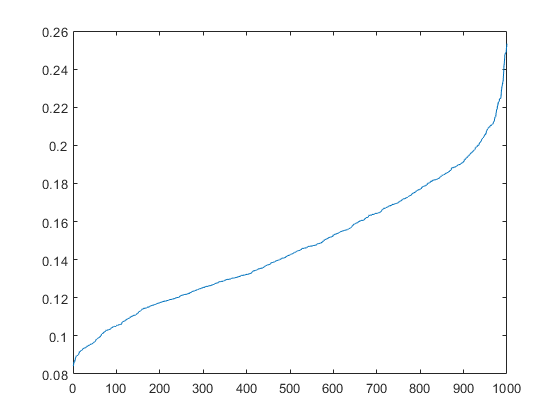

minpts = 60;
orderedDistance = sort(Distance, 'ascend');
plot(sort(orderedDistance(minpts,:)));


epsilon = 0.22;
[DBSCANidx, corepts] = dbscan(Distance,epsilon,minpts,'Distance','precomputed');
nDBSCANCluster = unique(DBSCANidx)

nDBSCANCluster = 1

%%nSubSample = 1900;
%%rng('default') % for reproducibility
%%randRows = randperm(size(X, 1), nSubSample);
%%X = X(randRows', :);
epsilon=0.22;
minpts=32;
idx = dbscan(X,epsilon,minpts);
%%gscatter(X(:,1),X(:,2),idx);
%%title('DBSCAN Using Euclidean Distance Metric')

figure
for i = 1:size(idx,1)
    pointer = idx(i);
    scatter(Y(idx==pointer,1),Y(idx==pointer,2),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[rand() rand() rand()])  % random colours
    hold on
end
title('2-D t-SNE embedding of DBSCAN clusters')
legend

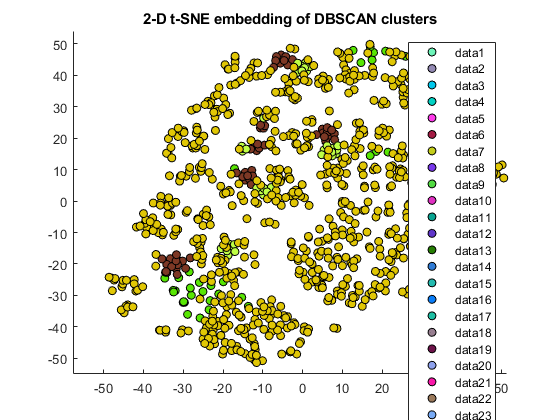

hold off

[DBSCANidx, corepts] = dbscan(Distance,epsilon,30,'Distance','chebychev');
nDBSCANCluster = unique(DBSCANidx)

nDBSCANCluster = 1

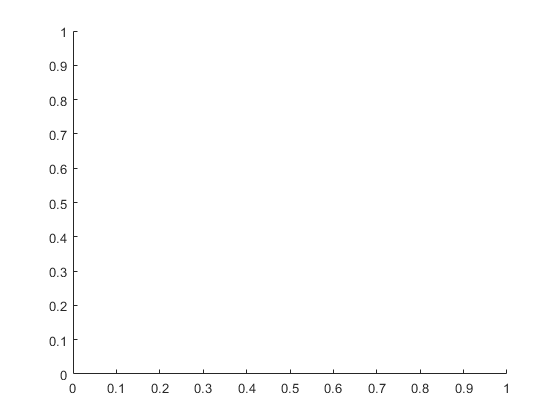

Y = tsne(X,'Algorithm','exact','Distance', "chebychev",'NumDimensions', 2);
hold on

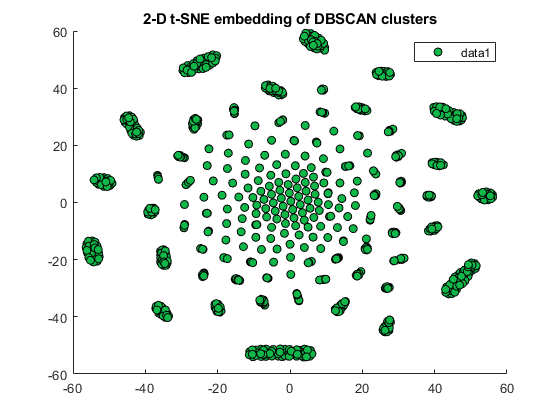

figure
for i = 1:size(nDBSCANCluster,1)
    pointer = nDBSCANCluster(i);
    scatter(Y(DBSCANidx==pointer,1),Y(DBSCANidx==pointer,2),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[rand() rand() rand()])  % random colours
    hold on
end
title('2-D t-SNE embedding of DBSCAN clusters')
legend
hold off

DBSCANidx= dbscan(Distance,0.10,30,'Distance','chebychev');
nDBSCANCluster = unique(DBSCANidx)

nDBSCANCluster =     -1
     1


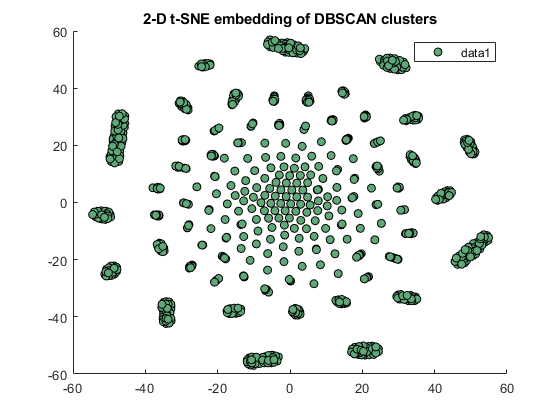


Y = tsne(X,'Algorithm','exact','Distance', "chebychev",'NumDimensions', 2);
hold on

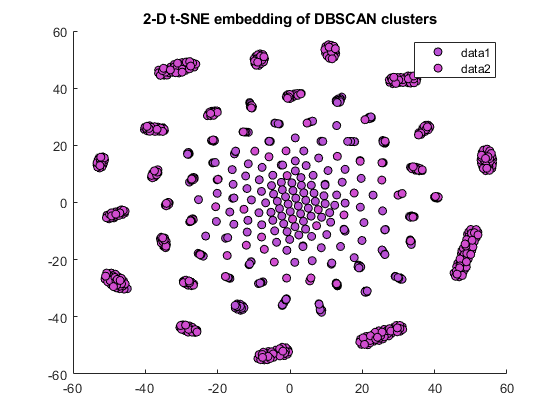

figure
for i = 1:size(nDBSCANCluster,1)
    pointer = nDBSCANCluster(i);
    scatter(Y(DBSCANidx==pointer,1),Y(DBSCANidx==pointer,2),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[rand() rand() rand()])  % random colours
    hold on
end
title('2-D t-SNE embedding of DBSCAN clusters')
legend
hold off

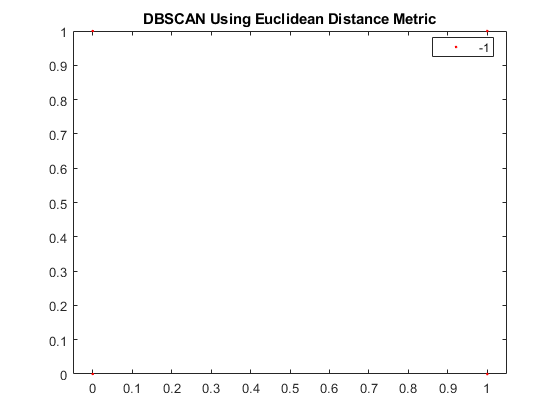

idx = dbscan(X,0.22,60); % The default distance metric is Euclidean distance
%Visualize the clustering.

gscatter(X(:,1),X(:,2),idx);
title('DBSCAN Using Euclidean Distance Metric')

#### Clustering evaluation

Our goal is to determine how well the data fits into a particular number of clusters using different evaluation criteria.

**Calinski-Harabasz criterion** ([https://it.mathworks.com/help/stats/clustering.evaluation.calinskiharabaszevaluation-class.html)](https://it.mathworks.com/help/stats/clustering.evaluation.calinskiharabaszevaluation-class.html)).

clust = [IDX3 IDX4 IDX5 IDX6]; %change this
eva1 = evalclusters(X,clust,'CalinskiHarabasz');
figure
plot(eva1)
eva1 %search for highest value


Davies-Bouldin criterion (https://it.mathworks.com/help/stats/clustering.evaluation.daviesbouldinevaluation-class.html).

eva2 = evalclusters(X,clust,'DaviesBouldin');
figure
plot(eva2)
eva2 %search for lowest value


**Silhouette criterion** ([https://it.mathworks.com/help/stats/clustering.evaluation.silhouetteevaluation-class.html](https://it.mathworks.com/help/stats/clustering.evaluation.silhouetteevaluation-class.html)).

eva3 = evalclusters(X,clust,'silhouette', 'Distance', @MixDistance);
figure
plot(eva3)
eva3 %highest value


Let's have a closer look at the silhouette of the most reasonable clusters hypothesis.

figure
silhouette(X,IDX5, @MixDistance);
figure
silhouette(X,IDX6,@MixDistance);